We want to look at LIGO noise and creating simulation of it. 

iligo = load("NOISE/iLIGOSensitivity.txt", "-ascii");
figure;
loglog(iligo(:,1),iligo(:,2));
xlabel("frequency (Hz)");
ylabel("sensitivity");
title("iLIGO Sensitivity Curve");

Next I'll use the provided PSD to generate a realization of initial ligo noise. 

FIXME: Improve this part by interpolating the iLIGO curve to a more finely spaced grid of frequency values. Then find the PSD at 50Hz and 700Hz from the interpolated values. Right now, as can be seen in the first plot, the flattening starts not at 50Hz but slightly off. Probably because the iLIGO curve was not specified exactly at 50Hz.

% interpolation o fmore fine PSD 
nfreq=(min(iligo(:,1)):1:max(iligo(:,1)))';
namp=interp1(iligo(:,1),iligo(:,2),nfreq);
niligo = [nfreq, namp]; % creates an interpolated version of iligo

sf = 16384;
nSamples = sf * 10; % ten seconds of data
filtorder = 512;
timeVec = (0:(nSamples-1))/sf;

% we need to normalize the iligo frequency vector to follow the rule that The frequencies
% must start from 0 and end at Fs/2. 

minFreq = 50; % using theh normalizations suggested in the slides
maxFreq = 700;
nyquistFreq = sf/2;

% creating the extended data and make the PSD 2 sided. 
validIdx = (niligo(:,1) >= minFreq+1) & (niligo(:,1) <= maxFreq-1);
iligoTrunc = niligo(validIdx, :);
psdstart = iligoTrunc(1, 2)/2;   % PSD at 50 Hz
psdend = iligoTrunc(end, 2)/2; % PSD at 700 Hz

freqPos = [minFreq; iligoTrunc(:,1); maxFreq];
psdPos = ([psdstart; iligoTrunc(:,2)/2; psdend])/2;

freqNeg = -flipud(freqPos(2:end-1));
psdNeg = flipud(psdPos(2:end-1));

% we have to fill the frequencies between minFreq and -minFreq as well as
% the values between max freq to nyquist freq

freqGap = (0:minFreq-1)';
psdGap = repmat(psdPos(1),length(freqGap),1) % these are not the real values, but just the value at the value

psdGap = 1.0e-22 *

    0.3686
    0.3686
    0.3686
    0.3686
    0.3686
    0.3686
    0.3686
    0.3686
    0.3686
    0.3686
    0.3686
    0.3686
    0.3686
    0.3686
    0.3686


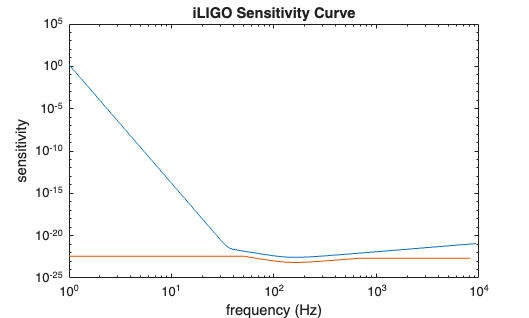


freqAbove = (maxFreq:nyquistFreq)';
psdAbove = repmat(psdPos(end),length(freqAbove),1);

psdBelow = flip(psdAbove);
freqBelow = -flip(freqAbove);

%freqBelow; freqNeg; 
%psdBelow; psdNeg; 
freqExtend = [freqGap; freqPos; freqAbove];
psdExtend = [psdGap; psdPos; psdAbove];

% this goes from -nyquist to nyquist, but the only 'interesting' part is +-
% 50 to 700 Hz 
iligoExtended = [freqExtend, psdExtend];

%SDM: Added plotting of psdExtended
hold on;
loglog(freqExtend,psdExtend);

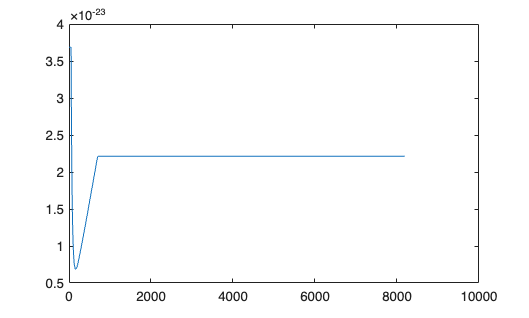

drawnow;

figure;
plot(freqExtend, psdExtend);

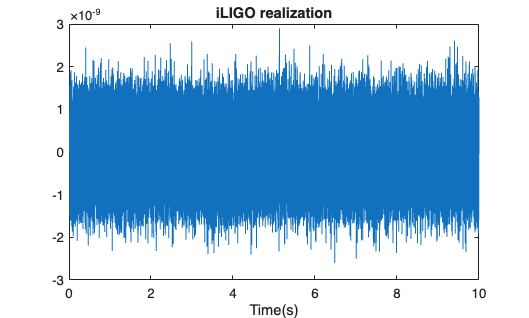


%FIXME This function expects a two-sided PSD but you are giving it the
%square-root of a one-sided PSD, which is the data given in
%iLIGOSensitivity.txt. Correct this part.
outNoise = statgaussnoisegen(nSamples,iligoExtended,512,sf);
figure;
plot(timeVec, outNoise);
xlabel("Time(s)");
title("iLIGO realization")

Now I'm going to estimate the PSD of the generated noise and compare it to the input value

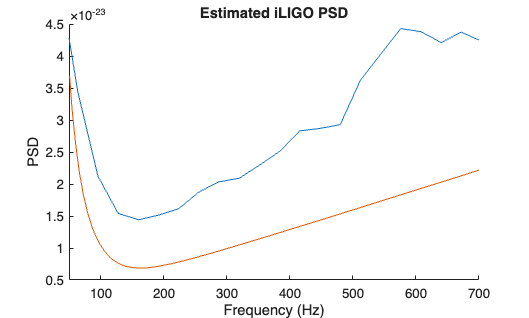

[ppx,f] = pwelch(outNoise,filtorder, [],[],sf);
figure; 
hold on;
loglog(f,ppx);
%FIXME As you can see, the estimated and target curves do not match. This
%is because of the error noted in the previous comment.
loglog(freqExtend,psdExtend);
xlim([50,700]); % we only want to plot in the truncated reigon, as our PSD would be different outside.
xlabel("Frequency (Hz)");
ylabel("PSD");
title("Estimated iLIGO PSD");